## Measure size of clusters in Spectrograms

The current script elucidates the methodology for gauging the dimensions of point clusters within spectrograms. The illustrations employed herein are derived from the execution of the live script entitled "createClusterSpectrogram.mlx". The two  spectrograms used here have been archived as image files. It is important to underscore that the strategy adopted in this instance is predicated solely on rudimentary image processing techniques. We explicitly refrain from the application of neural network methodologies in this process.

#### Procedrue to measure the size of a cluster of points in Spectrograms

- read in the spectrogram image file.

- create an image mask function that can extract out signals within a target level.

- retain the extracted image as a black-and-white image.

- "solidify" the cluster by filling-in holes and making the cluster a solid object.

-  removing objects within the image that are less than certain pixels.

- calculating the centroids of the disc-like object together with its diameter

#### Procedure to create an image mask function to extract signals

- use the colorThresholder app on the image

- select RGB as the choice of analysis space

- move mouse to "select a region of colors", the region being the signal level color bar.

- use the "export function" to generate the mask function. 

### Example 1 -- Measuring the size of a big cluster in spectrograms

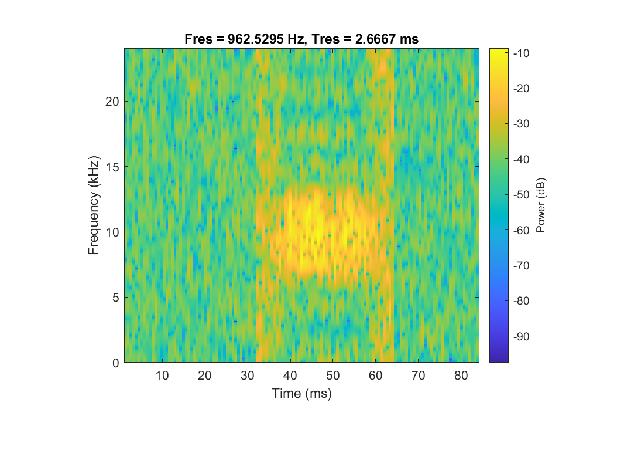

% load in spectrogram image
ibig = imread("bigCluster.png");
imshow(ibig)

#### Use the colorThresholder app to create a mask function

The created mask function (createmask) is used to segment out regions based on the pixel color.  In this case we use the color bar on the right to select regions between 60-80dB. 

Reference:  [https://www.mathworks.com/help/images/image-segmentation-using-the-color-thesholder-app.html](https://www.mathworks.com/help/images/image-segmentation-using-the-color-thesholder-app.html)

colorThresholder(ibig)  % generate createMask function

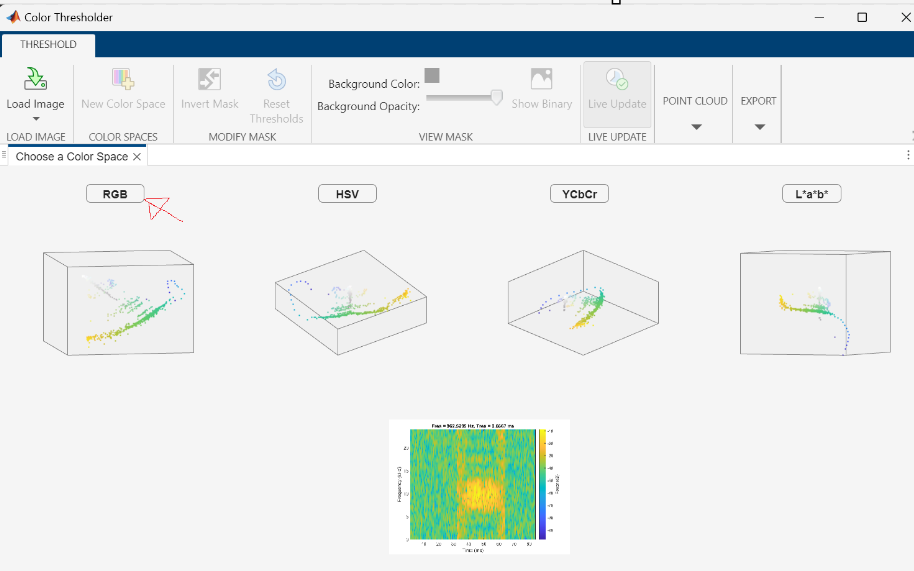

Select the RGB color space on the left.

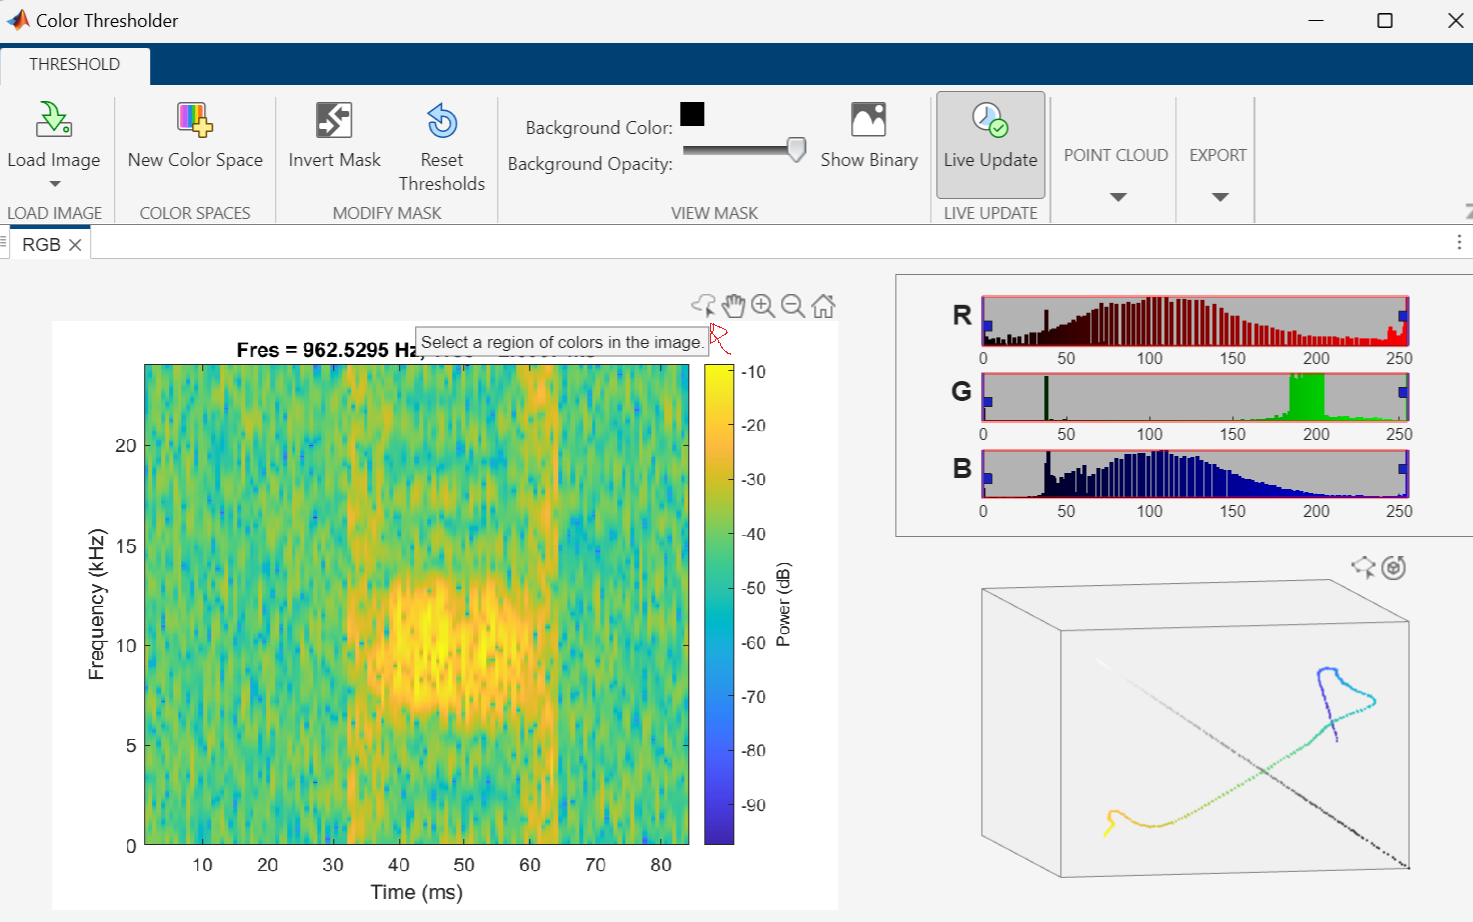

Click the "select a region of colors" option at the upper right corner of the image.

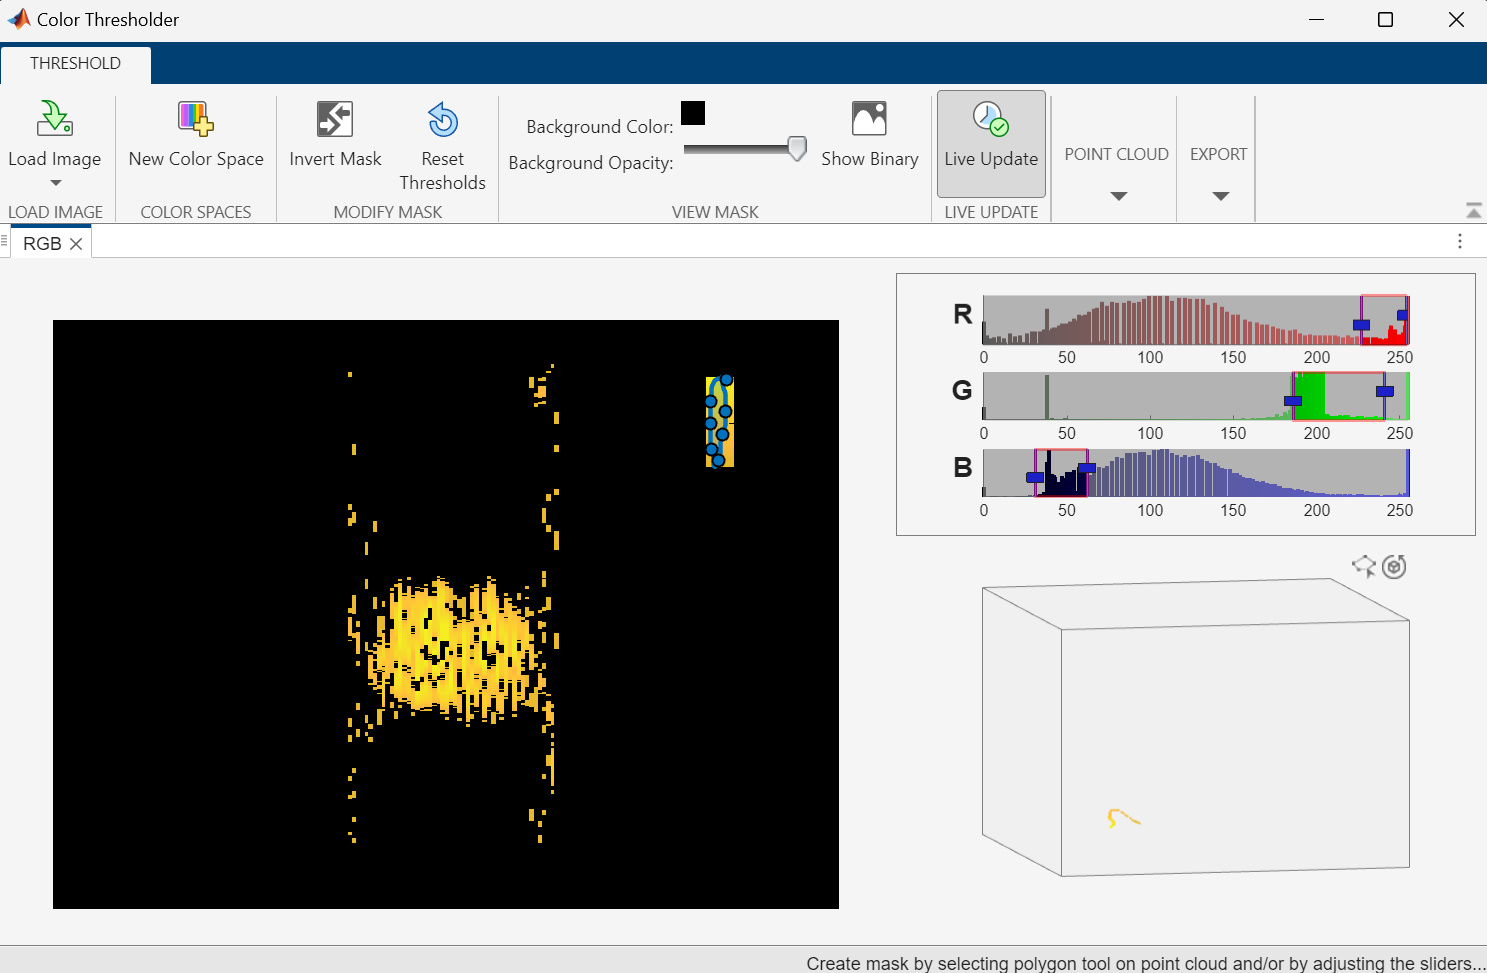

Use the mouse to draw a circle on the color bar, this will select the signal level of interest.

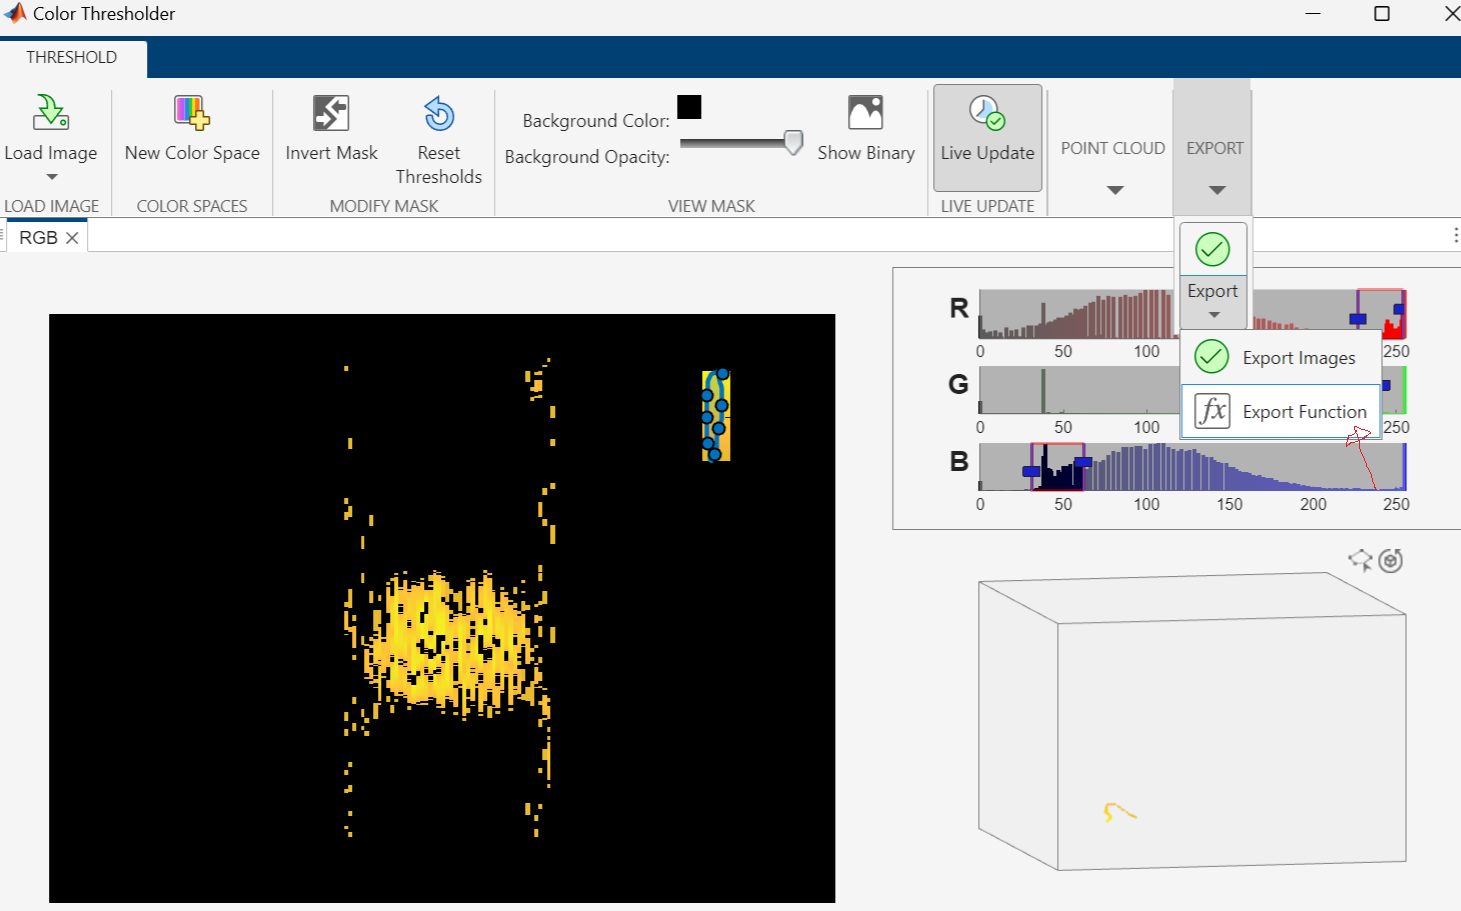

Click on Export Function and the createMask.m will be created.   

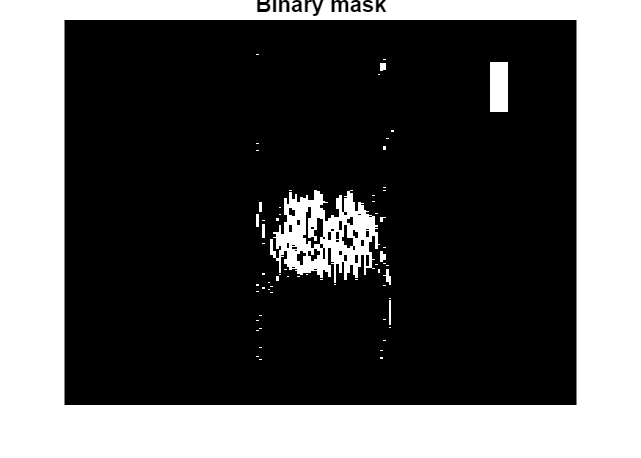

% using the mask function created to extract segments from the image

 [BW,maskedRGBImage] = createMask(ibig);
 imshow(BW)
 title('Binary mask')

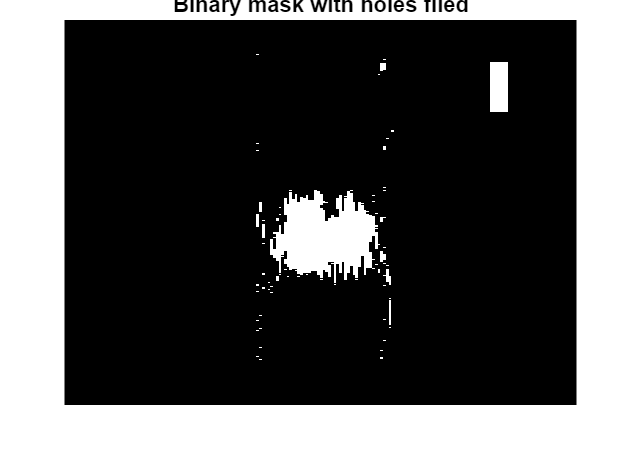

% use the imfill function to make the cluster points to become a solid
% piece
 FBW = imfill(BW,"holes");
imshow(FBW)
title('Binary mask with holes filed')

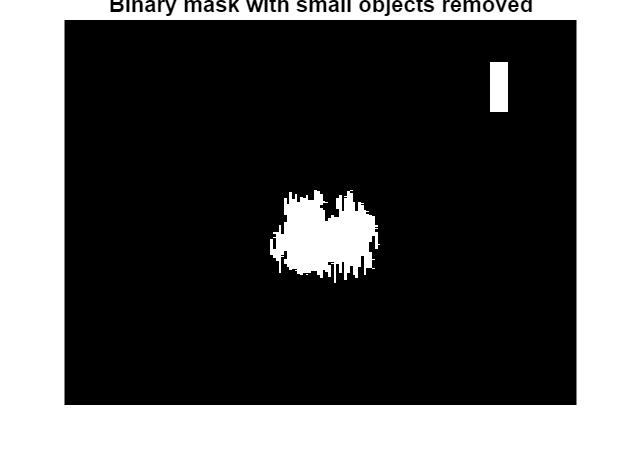

% use the bwareaopen function to remove objects smaller than 500 pixels
BW2 = bwareaopen(FBW,500);  % remove smaller obj
imshow(BW2) 
title('Binary mask with small objects removed')

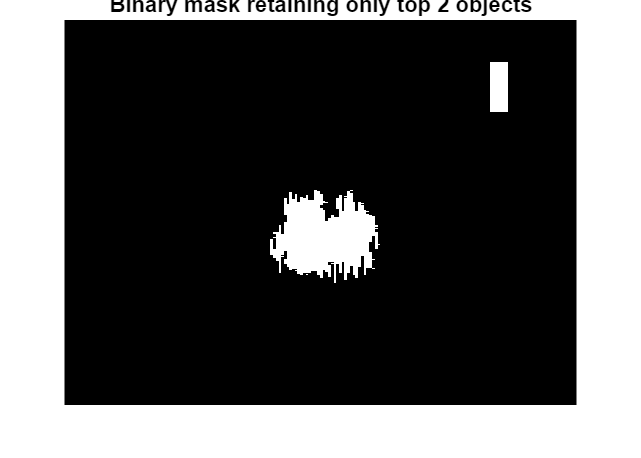

% Retaining only the largest 2 objects
BW_N = bwareafilt(BW2,2);  % retain N objects
imshow(BW_N)
title('Binary mask retaining only top 2 objects')

% finding the centroid of the object and measure the diameter 

stats = regionprops("table",BW_N,"Centroid", ...
    "MajorAxisLength","MinorAxisLength")

stats = 2×3 table
        Centroid        MajorAxisLength    MinorAxisLength
    ________________    _______________    _______________

    445.59    370.02        185.79             141.57     
    742.97     114.5        97.088             35.756     


centers = stats.Centroid;

% plot the image
imshow(BW_N)
hold on
plot(centers(:,1),centers(:,2),'b*')

diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = diameters/2;

% plot the circles
idx = 1; % choose the first object
viscircles(centers(idx,:),radii(idx))

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


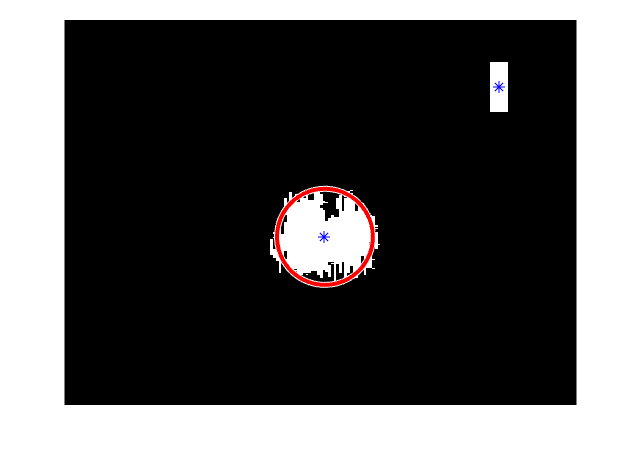

hold off

disp(['The radius of the cluster in bigcluster.png is ' num2str(radii(idx))])

The radius of the cluster in bigcluster.png is 81.8411


### Example 2 -- Measuring the size of a low-level cluster with a strong signal presence in spectrograms

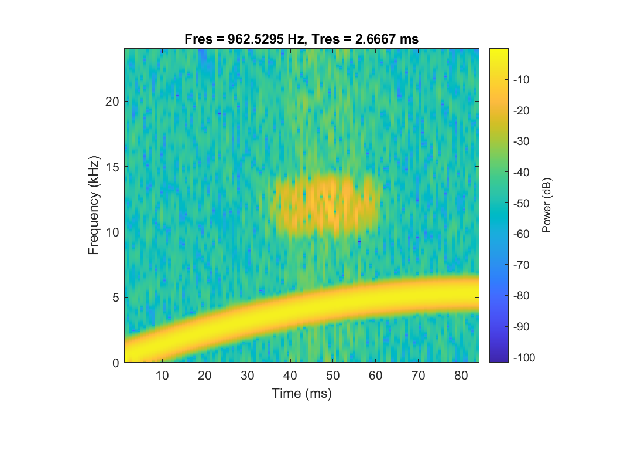

% load in spectrogram image
ismall = imread("smallCluster.png");
imshow(ismall)

colorThresholder(ismall)  % generate createMask2 function

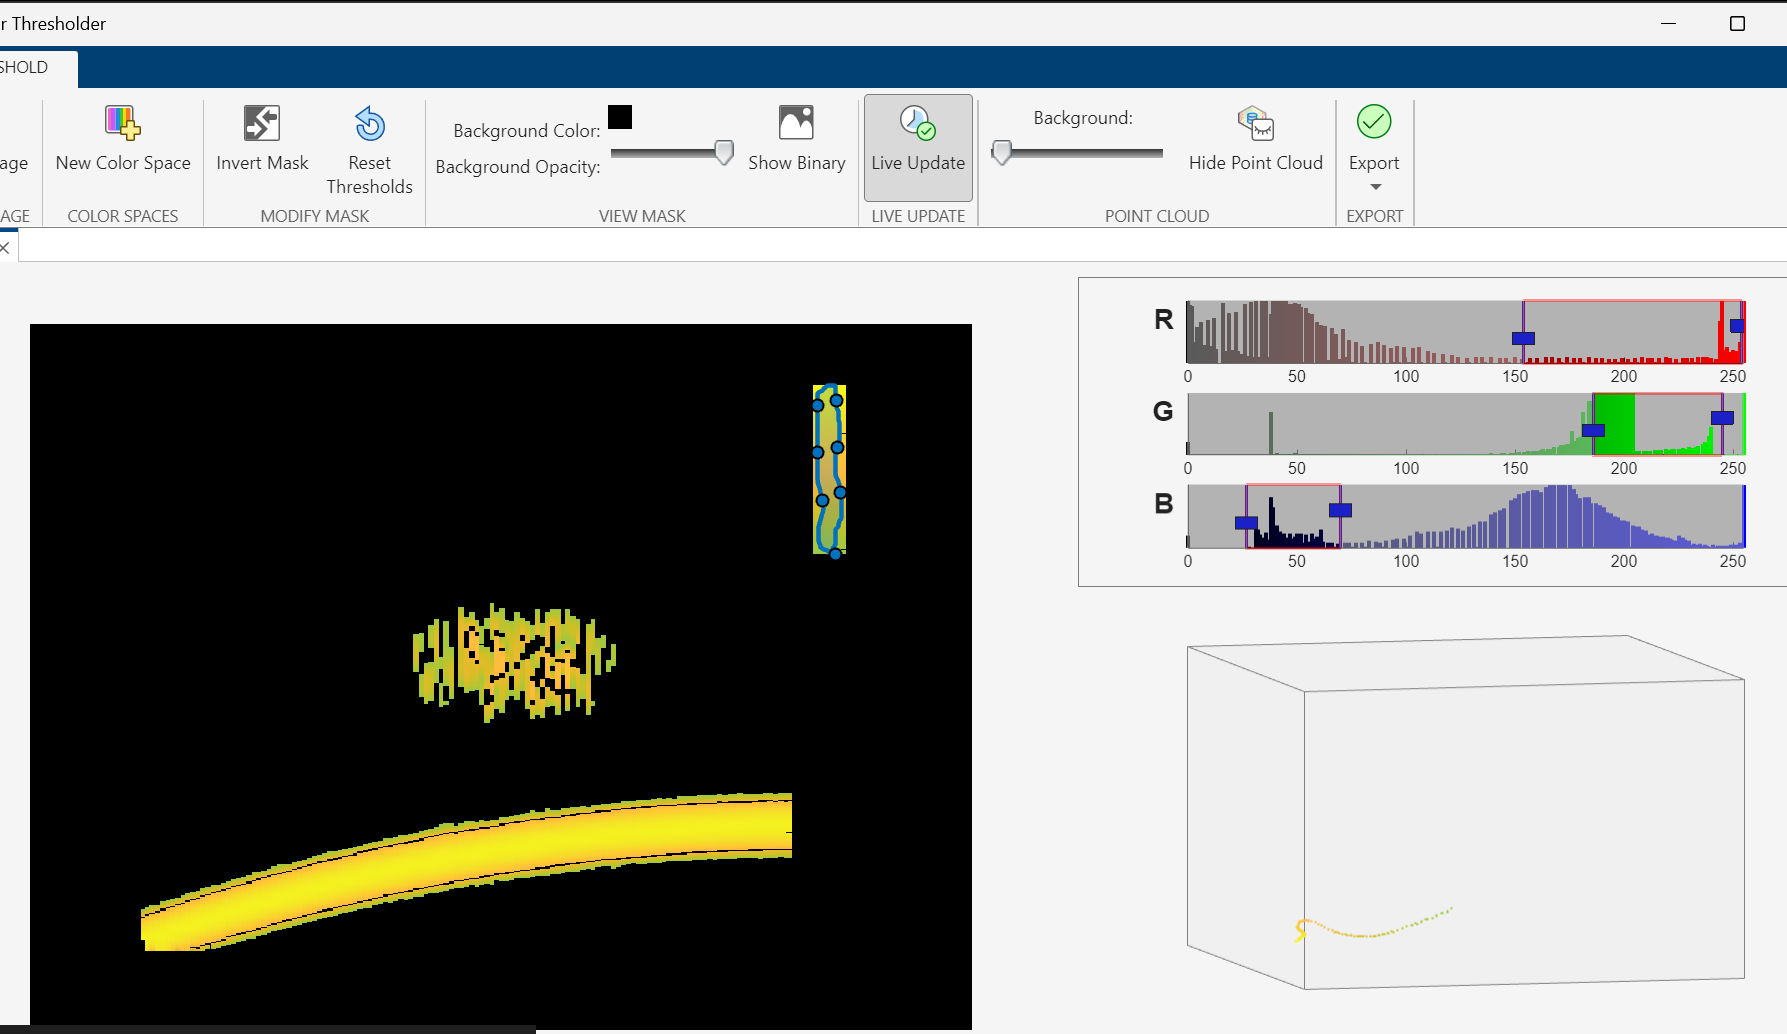

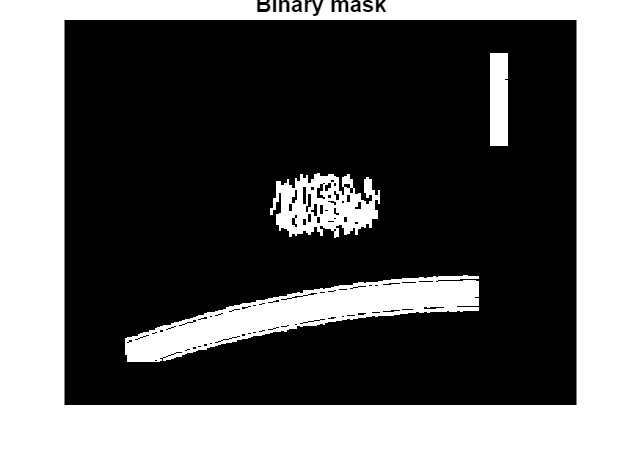

% using the mask function created to extract segments from the image


 [BW,maskedRGBImage] = createMask2(ismall);
 imshow(BW)
 title('Binary mask')

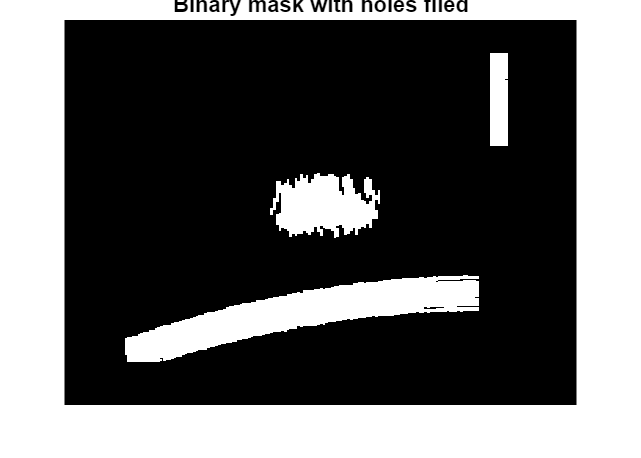

% use the imfill function to make the cluster points to become a solid
% piece
 FBW = imfill(BW,"holes");

imshow(FBW)
title('Binary mask with holes filed')

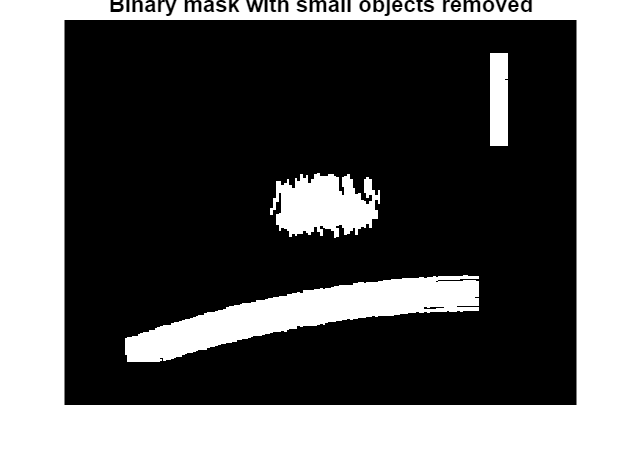

% use the bwareaopen function to remove objects smaller than 500 pixels
BW2 = bwareaopen(FBW,500);  % remove smaller obj
imshow(BW2) 

title('Binary mask with small objects removed')

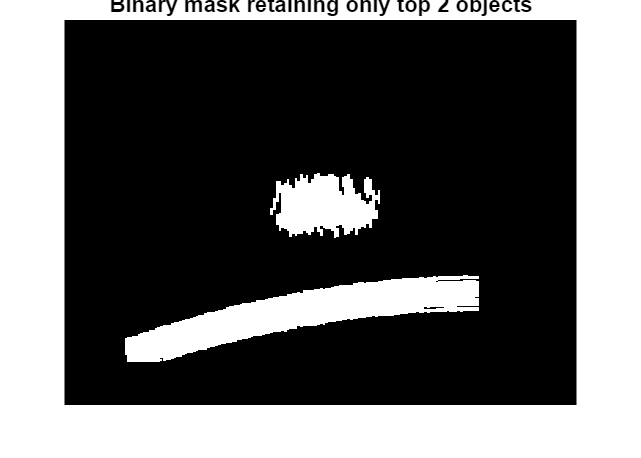

% Retaining only the largest 2 objects
BW_N = bwareafilt(BW2,2);  % retain N objects
imshow(BW_N)
title('Binary mask retaining only top 2 objects')

% finding the centroid of the object and measure the diameter 

stats = regionprops("table",BW_N,"Centroid", ...
    "MajorAxisLength","MinorAxisLength")

stats = 2×3 table
        Centroid        MajorAxisLength    MinorAxisLength
    ________________    _______________    _______________

    409.82    501.18        693.45             72.851     
    444.26    316.64         189.1             105.08     


centers = stats.Centroid;

% plot the image
imshow(BW_N)
hold on
plot(centers(:,1),centers(:,2),'b*')

diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = diameters/2;

% plot the circles
idx = 2; % choose the second object
viscircles(centers(idx,:),radii(idx))

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


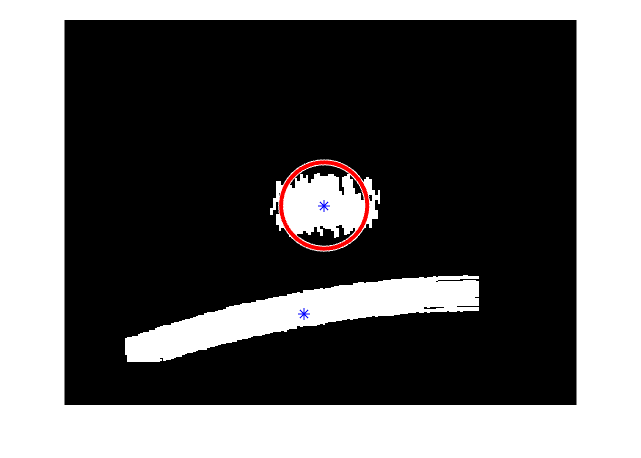

hold off

disp(['The radius of the cluster in smallCluster.png is ' num2str(radii(idx))])

The radius of the cluster in smallCluster.png is 73.5453


Copyright (c) 2024, The MathWorks, Inc.